clc
clear

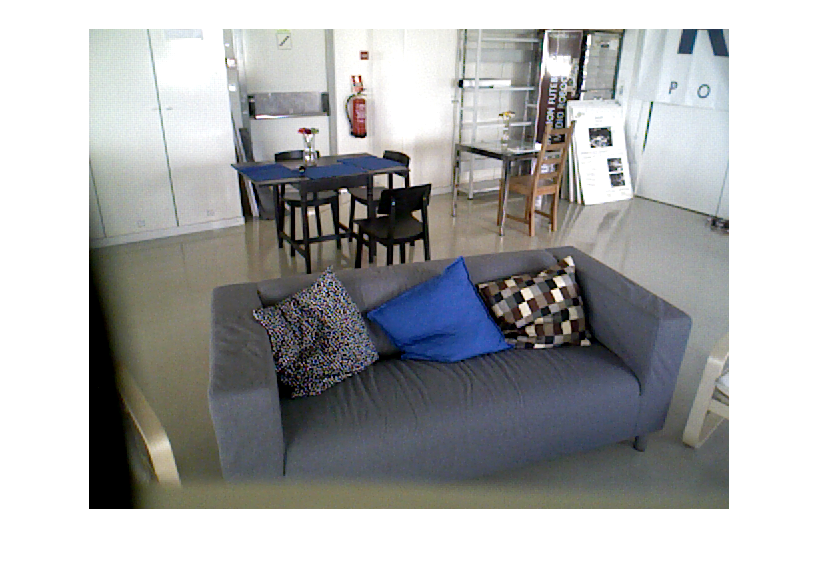

%image reading
image_10 = imread("rgb_image_10.png");
imshow(image_10)

% depth map
load depth_10.mat; 
depth_img_10 = single(depth_array) / 1000;

% camera calibration
load calib_asus.mat;
K=Depth_cam.K; % intrinsic matrix, a 3x3 matrix
Krgb=RGB_cam.K;

% Projection matrix (P)

R = eye(3); % Identity matrix for rotation, assuming no rotation
t = [0; 0; 0]; % Zero translation vector

% Constructing the 3x4 [R | t] matrix
Rt = [R, t]; % Concatenate R and t

% Creating a point cloud
points = [];


RGB_values =

     []



for u = 1:size(depth_img_10, 1)
    for v = 1:size(depth_img_10, 2)
        xy = compute_x_y(u, v, depth_img_10, K, Rt);
        x = xy(1);
        y = xy(2);
        z = xy(3);
        point = [x; y; z];
        points = [points; point'];
        
    end
end

Unrecognized function or variable 'colors'.

% Visualization using point cloud toolbox
ptCloud = pointCloud(points);  % Create a point cloud without color information
pcshow(ptCloud);               % Display the point cloud
xlabel('X');                   % Label X-axis
ylabel('Y');                   % Label Y-axis
zlabel('Z');                   % Label Z-axis


function xy = compute_x_y(u, v, depth_matrix, K, Rt)
    z = depth_matrix(u,v);
    K_inv = pinv(K);
    Rt_inv = pinv(Rt);
    uv_1 = [u; v; 1];
    xy = z * (Rt_inv * (K_inv * uv_1));
end
